# Experiment 3

# Bit error rate of Binary Phase Shift Keying (BPSK) in

# Additive White Gaussian Noise (AWGN)

## Communications Lab

## *190020039*

### Initialize Matlab

close all;
clear;
clc;

### Declaring some variables

% generate BPSK constellation as complex numbers
bpskcon = exp(1i*2*pi.*[0,1]/2);
% SNR array varying in the range of -10 to +10 dB in steps of 1 dB
snrdb=-10:10;
%no of elements in SNR array
nsnrdb = length(snrdb);

### Message signal

% no of symbols in mesaage array
nsym=20000;
% message bit array
m=randi([0,1],nsym,1);

### BPSK Modulation

% modulating message symbol array
% 0 mapped to -1 and 1 mapped to +1
mod=(m==0)*(-1)+(m==1)*(+1);

### Adding AWGN and Demodulating using ML

% declaring estimated Bit Error Rate (BER) array
ber_est = zeros(nsnrdb,1);
for k=1:nsnrdb
% calculating sigma from noise power
sigma=sqrt(1/(2*(10^(snrdb(k)/10))));
% adding AWGN to modulated signal
received = mod + sigma*randn(nsym,1)+1i*sigma*randn(nsym,1);
% DECLARING 2 ARRAYS USEFUL FOR ERROR CALCULATION
% creating array of  size (nsym,2) with 
% each row as constellation array
arr1=ones(nsym,2).*bpskcon;
% creating array size (nsym,2) with 
% each column as received signal array
arr2=[received,received];
% finding distance between 
% constellation points and received signal
% idx stores index(1 or 2) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% using index to get demodulated signal bit array 
% idx=1 is bit=1 and idx=2 is bit=0
demod=(idx==1)*(1);
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
ber_est(k)=sum(demod~=m)/nsym;
end

### Plotting Graphs

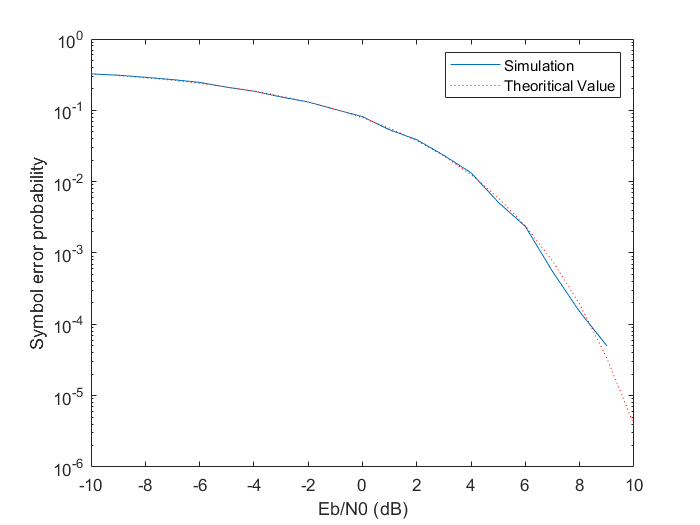

semilogy(snrdb,ber_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(snrdb/10); % raw SNR values
perr_th = qfunc(sqrt(2*snro)); % theoretical error
semilogy(snrdb,perr_th,':r'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation','Theoritical Value','Location','NorthEast');
hold off;